**P.3**

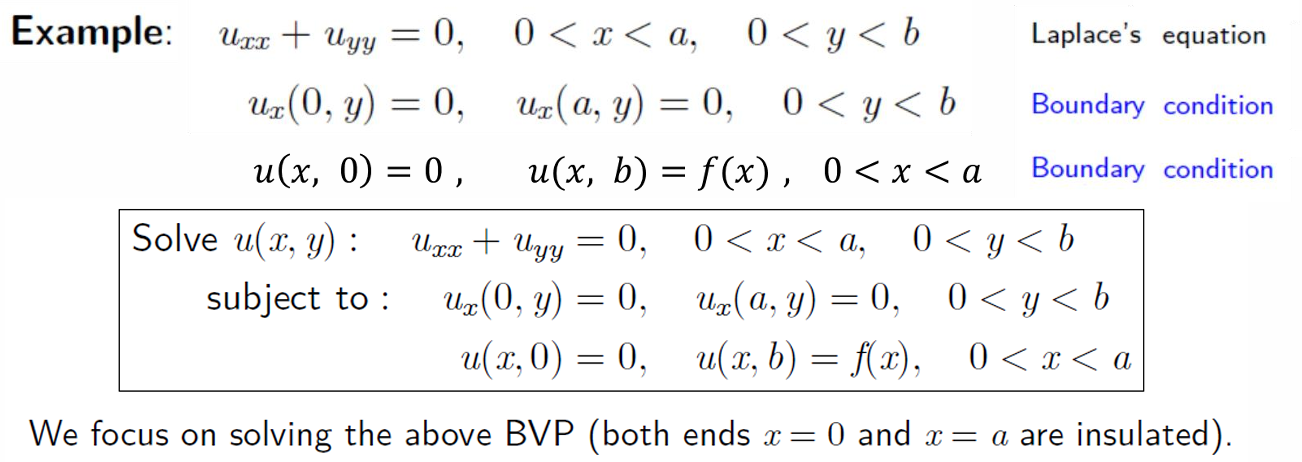

**Separation part**

clearvars;clc;
syms x y u(x,y) f(x) a b
assume([a b],"positive")

**Laplace equation**

LaplaceEq = diff(u,x,2) == - diff(u,y,2)

$$LaplaceEq(x, y) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=-\frac{\partial^{2}}{\partial y^{2}}u\left(x,y\right)$$

Dx = diff(u,x);
x0 = Dx(0,y) == 0;xa = Dx(a,y) == 0;
y0 = u(x,0) == 0; yb = u(x,b) == f(x);
syms X(x) Y(y)
SepVar = subs(LaplaceEq,u(x,y),X(x)*Y(y));
DX = diff(X,x);

**condition**

x0 = subs(x0,Dx(0,y),DX(0))

$$x0 = \left({\left(\frac{\partial }{\partial x}X\left(x\right)\right)|}_{x=0}\right)=0$$

xa = subs(xa,Dx(a,y),DX(a))

$$xa = \frac{\partial }{\partial a}X\left(a\right)=0$$

y0 = subs(y0,u(x,0),Y(0))

$$y0 = Y\left(0\right)=0$$

yb = subs(yb,u(x,b),Y(b))

$$yb = Y\left(b\right)=f\left(x\right)$$

SepVar = SepVar/(X(x)*Y(y))

$$SepVar(x, y) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}$$

syms lambda
assume(lambda,"positive")

**separation**

var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqY = var(2) == -lambda^2

$$eqY = -\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}=-\lambda^{2}$$

X(x) = dsolve(eqX,x0)

$$X(x) = C_{1}\,\cos\left(\lambda \,x\right)$$

X_0(x) = dsolve(cell2sym(var(1)) == 0,x0)

$$X\_0(x) = C_{1}$$

sln = subs(diff(X,x),x,a) == 0

$$sln(x) = -C_{1}\,\lambda \,\sin\left(a\,\lambda \right)=0$$

**Finding lambda**

[lambda,parameters,~] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{a}$$

Y(y) = expand(dsolve(eqY,y0))

$$Y(y) = C_{1}\,{\mathrm{e}}^{-\lambda \,y}-C_{1}\,{\mathrm{e}}^{\lambda \,y}$$

Y(y) = simplify(rewrite(Y,"sinh"))

$$Y(y) = -2\,C_{1}\,\sinh\left(\lambda \,y\right)$$

Y_0(y) = dsolve(cell2sym(var(2)) == 0,y0)

$$Y\_0(y) = C_{1}\,y$$

**Substitution**

syms A_0 A_n ustruct(x,y)
Y(y) = subs(Y,{'lambda','C1'},{lambda,-1/2});
X(x) = subs(X,{'lambda','C1'},{lambda,A_n});
ustruct_0(x,y) = subs(X_0(x)*Y_0(y),str2sym('C1^2'),A_0);
ustruct(x,y) = ustruct_0(x,y)+X(x)*Y(y)

$$ustruct(x, y) = A_{0}\,y+A_{n}\,\cos\left(\frac{\pi \,n\,x}{a}\right)\,\sinh\left(\frac{\pi \,n\,y}{a}\right)$$

**Fourier series part**

syms Sigma
ceff = coeffs(ustruct(x,b),cos(pi*n*x/a));
ceff = subs(ceff,{'A_0','A_n'},{1,1});
A_0 = 2/a*int(f,x,[0 a])/ceff(1)

$$A\_0 = \frac{2\,\int_{0}^{a}f\left(x\right)\mathrm{d}x}{a\,b}$$

A_n = 2/a*int(f*cos(pi*n*x/a),x,[0 a])/ceff(2)

$$A\_n = \frac{2\,\int_{0}^{a}\cos\left(\frac{\pi \,n\,x}{a}\right)\,f\left(x\right)\mathrm{d}x}{a\,\sinh\left(\frac{\pi \,b\,n}{a}\right)}$$

LaplaceSol = [Sigma,ustruct]

$$LaplaceSol(x, y) = \left(\begin{array}{cc} \Sigma & A_{0}\,y+A_{n}\,\cos\left(\frac{\pi \,n\,x}{a}\right)\,\sinh\left(\frac{\pi \,n\,y}{a}\right) \end{array}\right)$$

**P.22**

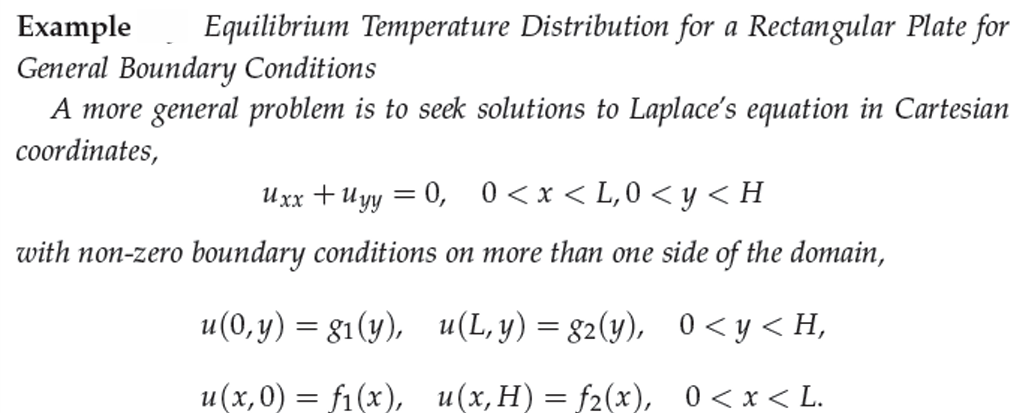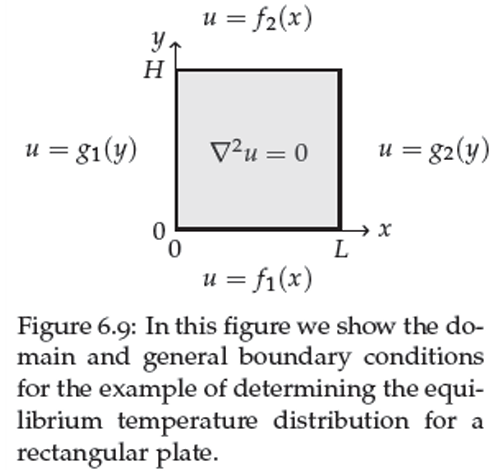

Separation part of U1

clear
clc
syms x y u(x,y) f1(x) f2(x) g1(y) g2(y) L H
assume([L H],"positive")
LaplaceEq = diff(u,x,2) == -diff(u,y,2)

$$LaplaceEq(x, y) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=-\frac{\partial^{2}}{\partial y^{2}}u\left(x,y\right)$$

x0 = u(0,y) == 0; xL = u(L,y) == 0;
y0 = u(x,0) == f1; yH = u(x,H) == f2;
syms X(x) Y(y)
SepVar = subs(LaplaceEq,u(x,y),X(x)*Y(y));
x0 = subs(x0,u(0,y),X(0))

$$x0 = X\left(0\right)=0$$

xL = subs(xL,u(L,y),X(L))

$$xL = X\left(L\right)=0$$

y0 = subs(y0,u(x,0),Y(0))

$$y0(x) = Y\left(0\right)=f_{1}\left(x\right)$$

yH = subs(yH,u(x,H),Y(H))

$$yH(x) = Y\left(H\right)=f_{2}\left(x\right)$$

SepVar = SepVar/(X(x)*Y(y))

$$SepVar(x, y) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}$$

syms lambda
assume(lambda,"positive")
var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqY = var(2) == -lambda^2

$$eqY = -\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}=-\lambda^{2}$$

X(x) = dsolve(eqX,x0)

$$X(x) = -C_{1}\,\sin\left(\lambda \,x\right)$$

x_0L(x) = dsolve(cell2sym(var(1))== 0,[x0,xL])

$$x\_0L(x) = 0$$

Y(y) = dsolve(eqY)

$$Y(y) = C_{1}\,{\mathrm{e}}^{\lambda \,y}+C_{2}\,{\mathrm{e}}^{-\lambda \,y}$$

Y(y) = collect(rewrite(Y,"sinhcosh"),["cosh","sinh"]);
sln = subs(X,x,L) == 0;
[lambda,parameters,~] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{L}$$

syms A_n B_n C_n ustruct(x,y)
Y(y) = subs(Y,[str2sym({'C1+C2','C1-C2'}),'lambda'],[{A_n,B_n},lambda])

$$Y(y) = A_{n}\,\cosh\left(\frac{\pi \,n\,y}{L}\right)+B_{n}\,\sinh\left(\frac{\pi \,n\,y}{L}\right)$$

X(x) = subs(X,{'C1','lambda'},{-1,lambda});
ustruct(x,y) = X(x)*Y(y)

$$ustruct(x, y) = \sin\left(\frac{\pi \,n\,x}{L}\right)\,\left(A_{n}\,\cosh\left(\frac{\pi \,n\,y}{L}\right)+B_{n}\,\sinh\left(\frac{\pi \,n\,y}{L}\right)\right)$$

syms Sigma
LaplaceSol_1 = Sigma*ustruct

$$LaplaceSol\_1(x, y) = \Sigma \,\sin\left(\frac{\pi \,n\,x}{L}\right)\,\left(A_{n}\,\cosh\left(\frac{\pi \,n\,y}{L}\right)+B_{n}\,\sinh\left(\frac{\pi \,n\,y}{L}\right)\right)$$

Fourier series part

A_n = 2/L*int(f1*sin(pi*n*x/L),x,[0 L])

$$A\_n = \frac{2\,\int_{0}^{L}\sin\left(\frac{\pi \,n\,x}{L}\right)\,f_{1}\left(x\right)\mathrm{d}x}{L}$$

ceff = children(subs(coeffs(ustruct(x,H),sin(pi*n*x/L)),'B_n',1));
B_n = (C_n-cell2sym(ceff(2)))/cell2sym(ceff(1))

$$B\_n = \frac{C_{n}-A_{n}\,\cosh\left(\frac{\pi \,H\,n}{L}\right)}{\sinh\left(\frac{\pi \,H\,n}{L}\right)}$$

C_n = 2/L*int(f2*sin(pi*n*x/L),x,[0 L])

$$C\_n = \frac{2\,\int_{0}^{L}\sin\left(\frac{\pi \,n\,x}{L}\right)\,f_{2}\left(x\right)\mathrm{d}x}{L}$$

u1(x,y) = Sigma*subs(ustruct,'B_n',B_n)

$$u1(x, y) = \Sigma \,\sin\left(\frac{\pi \,n\,x}{L}\right)\,\left(A_{n}\,\cosh\left(\frac{\pi \,n\,y}{L}\right)+\frac{\sinh\left(\frac{\pi \,n\,y}{L}\right)\,\left(C_{n}-A_{n}\,\cosh\left(\frac{\pi \,H\,n}{L}\right)\right)}{\sinh\left(\frac{\pi \,H\,n}{L}\right)}\right)$$

Separation part of U2

LaplaceEq = -diff(u,x,2) == diff(u,y,2)

$$LaplaceEq(x, y) = -\frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=\frac{\partial^{2}}{\partial y^{2}}u\left(x,y\right)$$

x0 = u(0,y) == g1; xL = u(L,y) == g2;
y0 = u(x,0) == 0; yH = u(x,H) == 0;
syms X(x) Y(y)
SepVar = subs(LaplaceEq,u(x,y),X(x)*Y(y));
x0 = subs(x0,u(0,y),X(0))

$$x0(y) = X\left(0\right)=g_{1}\left(y\right)$$

XL = subs(xL,u(L,y),X(L))

$$XL(y) = X\left(L\right)=g_{2}\left(y\right)$$

y0 = subs(y0,u(x,0),Y(0))

$$y0 = Y\left(0\right)=0$$

yH = subs(yH,u(x,H),Y(H))

$$yH = Y\left(H\right)=0$$

SepVar = SepVar/(X(x)*Y(y))

$$SepVar(x, y) = -\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}$$

syms mu
assume(mu,"positive")
var = children(SepVar);
eqX = var(1) == -mu^2

$$eqX = -\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\mu^{2}$$

eqY = var(2) == -mu^2

$$eqY = \frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}=-\mu^{2}$$

Y(y) = dsolve(eqY,y0)

$$Y(y) = -C_{1}\,\sin\left(\mu \,y\right)$$

Y_0H(y) = dsolve(cell2sym(var(2)) == 0,[y0,yH])

$$Y\_0H(y) = 0$$

X(x) = dsolve(eqX)

$$X(x) = C_{1}\,{\mathrm{e}}^{\mu \,x}+C_{2}\,{\mathrm{e}}^{-\mu \,x}$$

X(x) = collect(rewrite(X,"sinhcosh"),["cosh","sinh"]);
sln = subs(Y,y,H) == 0;
[mn,parameters,~] = solve(sln,mu,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
mu = subs(mu,parameters,n)

$$mu = \mu$$

syms A_n B_n C_n ustruct(x,y)
X(x) = subs(X,[str2sym({'C1+C2','C1-C2'}),'mu'],[{A_n,B_n},mu])

$$X(x) = A_{n}\,\cosh\left(\mu \,x\right)+B_{n}\,\sinh\left(\mu \,x\right)$$

Y(y) = subs(Y,{'C1','mu'},{-1,mu});
ustruct(x,y) = X(x)*Y(y)

$$ustruct(x, y) = \sin\left(\mu \,y\right)\,\left(A_{n}\,\cosh\left(\mu \,x\right)+B_{n}\,\sinh\left(\mu \,x\right)\right)$$

syms Sigma
LaplaceSol_2 = [Sigma,ustruct]

$$LaplaceSol\_2(x, y) = \left(\begin{array}{cc} \Sigma & \sin\left(\mu \,y\right)\,\left(A_{n}\,\cosh\left(\mu \,x\right)+B_{n}\,\sinh\left(\mu \,x\right)\right) \end{array}\right)$$

Fourier series part

A_n = 2/H*int(g1*sin(pi*n*y/H),y,[0 H])

$$A\_n = \frac{2\,\int_{0}^{H}\sin\left(\frac{\pi \,n\,y}{H}\right)\,g_{1}\left(y\right)\mathrm{d}y}{H}$$

ceff = children(subs(coeffs(ustruct(L,y),sin(pi*n*y/H)),'B_n',1));
B_n = (C_n-cell2sym(ceff(2)))/cell2sym(ceff(1))

$$B\_n = -\frac{\sinh\left(L\,\mu \right)-C_{n}+A_{n}\,\cosh\left(L\,\mu \right)}{\sin\left(\mu \,y\right)}$$

C_n = 2/H*int(g2*sin(pi*n*y/H),y,[0 H])

$$C\_n = \frac{2\,\int_{0}^{H}\sin\left(\frac{\pi \,n\,y}{H}\right)\,g_{2}\left(y\right)\mathrm{d}y}{H}$$

u2(x,y) = Sigma*subs(ustruct,'B_n',B_n)

$$u2(x, y) = \Sigma \,\sin\left(\mu \,y\right)\,\left(A_{n}\,\cosh\left(\mu \,x\right)-\frac{\sinh\left(\mu \,x\right)\,\left(\sinh\left(L\,\mu \right)-C_{n}+A_{n}\,\cosh\left(L\,\mu \right)\right)}{\sin\left(\mu \,y\right)}\right)$$

u(x,y) = str2sym('u1(x,y)+u2(x,y)')

$$u(x, y) = u_{1}\left(x,y\right)+u_{2}\left(x,y\right)$$

**P.29**

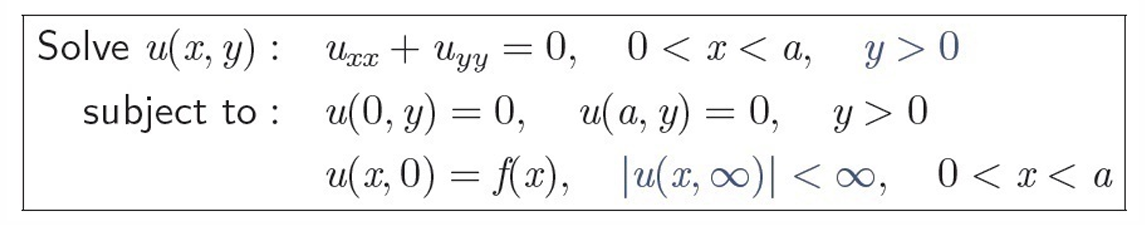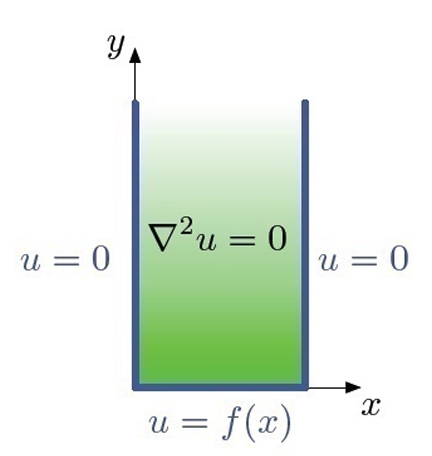

**Separation part**

clear
clc
syms x y u(x,y) f(x) a
assume(a,"positive")
LaplaceEq = diff(u,x,2) == - diff(u,y,2)

$$LaplaceEq(x, y) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=-\frac{\partial^{2}}{\partial y^{2}}u\left(x,y\right)$$

x0 = u(0,y) == 0;xa = u(a,y) == 0;
y0 = u(x,0) == f(x);
syms X(x) Y(y)
SepVar = subs(LaplaceEq,u(x,y),X(x)*Y(y));
x0 = subs(x0,u(0,y),X(0))

$$x0 = X\left(0\right)=0$$

xa = subs(xa,u(a,y),X(a))

$$xa = X\left(a\right)=0$$

y0 = subs(y0,u(x,0),Y(0))

$$y0 = Y\left(0\right)=f\left(x\right)$$

y_inf = Y(inf) == str2sym('bounded')

$$y\_inf = Y\left(\infty \right)=\mathrm{bounded}$$

SepVar = SepVar/(X(x)*Y(y))

$$SepVar(x, y) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}$$

syms lambda
assume(lambda,"positive")

**Separation**

var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqY = var(2) == -lambda^2

$$eqY = -\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}=-\lambda^{2}$$

X(x) = subs(dsolve(eqX,x0),str2sym('-C1'),'C2')

$$X(x) = C_{2}\,\sin\left(\lambda \,x\right)$$

Y(y) = subs(dsolve(eqY),'C1',0)

$$Y(y) = C_{2}\,{\mathrm{e}}^{-\lambda \,y}$$

sln = subs(X,x,a) == 0

$$sln(x) = C_{2}\,\sin\left(a\,\lambda \right)=0$$

[lambda,parameter,~] = solve(sln,lambda,"ReturnConditions",true)

$$lambda = \frac{\pi \,k}{a}$$

$$parameter = k$$

n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameter,n)

$$lambda = \frac{\pi \,n}{a}$$

syms A_n ustruct(x,y,n)
X(x,n) = subs(X,{'C2','lambda'},{1,lambda})

$$X(x, n) = \sin\left(\frac{\pi \,n\,x}{a}\right)$$

Y(y,n) = subs(Y,{'C2','lambda'},{A_n,lambda})

$$Y(y, n) = A_{n}\,{\mathrm{e}}^{-\frac{\pi \,n\,y}{a}}$$

ustruct(x,y,n) = X(x,n)*Y(y,n)

$$ustruct(x, y, n) = A_{n}\,{\mathrm{e}}^{-\frac{\pi \,n\,y}{a}}\,\sin\left(\frac{\pi \,n\,x}{a}\right)$$

**Fourier integral part**

f(x) = (x+0.5)^3; ustruct = subs (ustruct, a,1)

$$ustruct(x, y, n) = A_{n}\,\sin\left(\pi \,n\,x\right)\,{\mathrm{e}}^{-\pi \,n\,y}$$

a = 1; An = 2/a*int(f*sin(pi*n*x/a),x,[0 a])

$$An = -\frac{2\,\left(6\,\sin\left(\pi \,n\right)+n^{3}\,\pi^{3}\,\left(\frac{27\,\cos\left(\pi \,n\right)}{8}-\frac{1}{8}\right)-\pi \,n\,\left(9\,\cos\left(\pi \,n\right)-3\right)-\frac{27\,n^{2}\,\pi^{2}\,\sin\left(\pi \,n\right)}{4}\right)}{n^{4}\,\pi^{4}}$$

syms Sigma
LaplaceSol = [Sigma ustruct]

$$LaplaceSol(x, y, n) = \left(\begin{array}{cc} \Sigma & A_{n}\,\sin\left(\pi \,n\,x\right)\,{\mathrm{e}}^{-\pi \,n\,y} \end{array}\right)$$

% LaplaceSol = symsum(subs (ustruct, {A_n, a}, {An,1}),n,1,inf)
Sol = symsum(subs(ustruct, A_n, An),n,1,30)

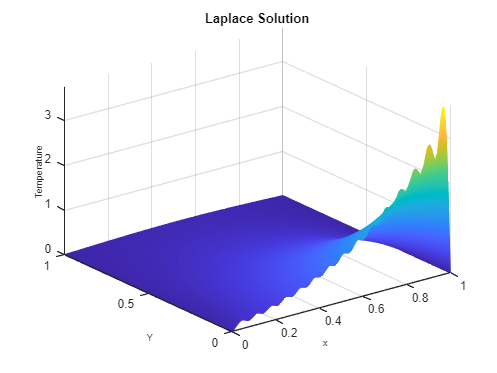

clf; figure
fsurf(Sol, [0 1 0 1], "EdgeColor", "interp") 
title("Laplace Solution")
xlabel('x', 'Fontsize',8);
ylabel('Y', 'Fontsize',8)
zlabel('Temperature', 'Fontsize',8)

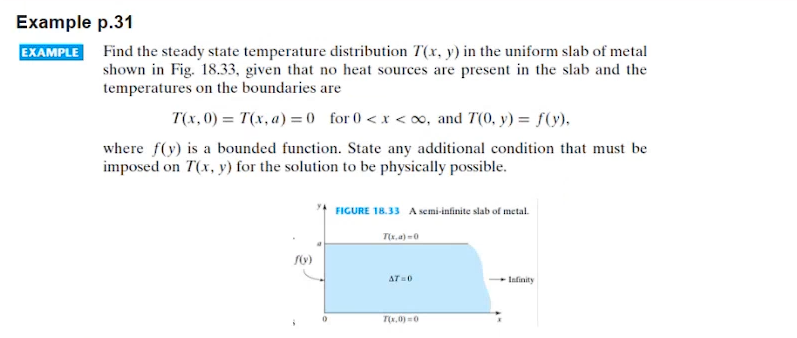

Separating part

clear
clc
clearvars
syms x y u(x,y) f(y) a
assume(a,"positive")
LaplaceEq = -diff(u,x,2) == diff(u,y,2)

$$LaplaceEq(x, y) = -\frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=\frac{\partial^{2}}{\partial y^{2}}u\left(x,y\right)$$

y0 = u(x,0) == 0; ya = u(x,a) == 0;
x0 = u(0,y) == f(y);
syms X(x) Y(y)
SepVar = subs(LaplaceEq,u(x,y),X(x)*Y(y));
y0 = subs(y0,u(x,0),Y(0))

$$y0 = Y\left(0\right)=0$$

ya = subs(ya,u(x,0),Y(a))

$$ya = u\left(x,a\right)=0$$

x0 = subs(x0,u(0,ya),X(0))

$$x0 = u\left(0,y\right)=f\left(y\right)$$

x_inf = X(inf) == str2sym('bounded')

$$x\_inf = X\left(\infty \right)=\mathrm{bounded}$$

SepVar = SepVar/(X(x)*Y(y))

$$SepVar(x, y) = -\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}$$

syms lambda
assume(lambda,"positive")
var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = -\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqY = var(2) == -lambda^2

$$eqY = \frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}=-\lambda^{2}$$

Y(y) = subs(dsolve(eqY,y0),str2sym('-C1'),'C2')

$$Y(y) = C_{2}\,\sin\left(\lambda \,y\right)$$

X(x) = subs(dsolve(eqX),'C1',0)

$$X(x) = C_{2}\,{\mathrm{e}}^{-\lambda \,x}$$

sln = subs(Y,y,a) == 0;
[lambda,parameters,~] = solve(sln, lambda, "ReturnConditions", true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{a}$$

syms A_n ustruct(x,y)
Y(y) = subs(Y,{'C2','lambda'},{1,lambda});
X(x) = subs(X,{'C2','lambda'},{A_n,lambda});
ustruct(x,y) = X(x)*Y(y)

$$ustruct(x, y) = A_{n}\,{\mathrm{e}}^{-\frac{\pi \,n\,x}{a}}\,\sin\left(\frac{\pi \,n\,y}{a}\right)$$

syms Sigma
LaplaceSol = [Sigma,ustruct]

$$LaplaceSol(x, y) = \left(\begin{array}{cc} \Sigma & A_{n}\,{\mathrm{e}}^{-\frac{\pi \,n\,x}{a}}\,\sin\left(\frac{\pi \,n\,y}{a}\right) \end{array}\right)$$

Fourier integral parrt

A_n = 2/a*int(f*sin(pi*n*y/a),y,[0,a])

$$A\_n = \frac{2\,\int_{0}^{a}\sin\left(\frac{\pi \,n\,y}{a}\right)\,f\left(y\right)\mathrm{d}y}{a}$$

**P.49**

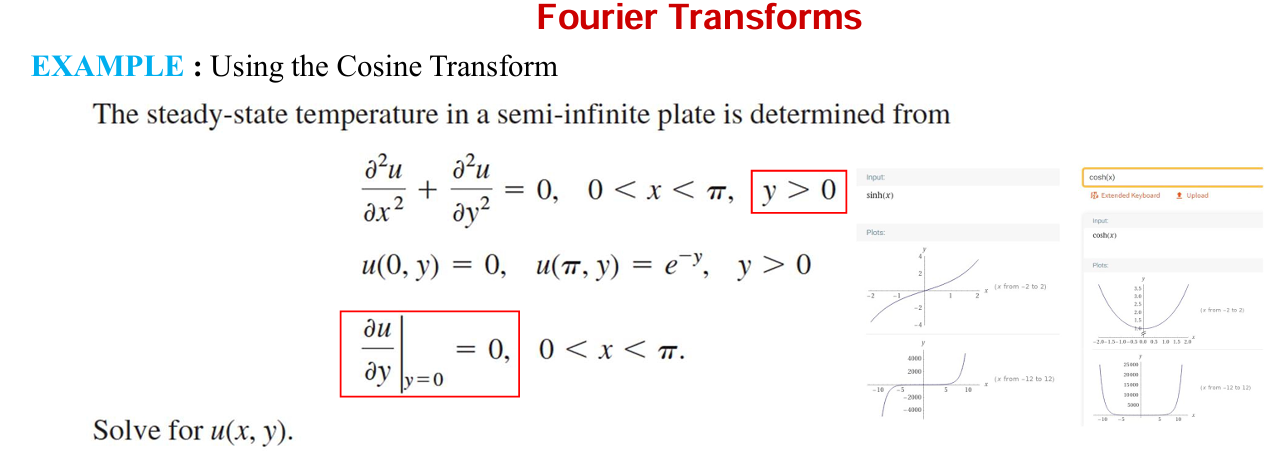

clear
clc
clearvars
syms x y w u(x,y) U_c(x,w) X(x) A B
Dy = diff(u,y);
D2y = diff(Dy,y);
D2x = diff(u,x,2);
eqn = fourier(D2x+D2y == 0,y,w);
eqn = expand(subs(eqn,{fourier(D2x,y,w),fourier(u,y,w)},{subs(D2x,{u,y},{U_c,w}),U_c+Dy(x,0)/w^2}))

$$eqn(x) = \frac{\partial^{2}}{\partial x^{2}}U_{c}\left(x,w\right)-\left({\left(\frac{\partial }{\partial y}u\left(x,y\right)\right)|}_{y=0}\right)-w^{2}\,U_{c}\left(x,w\right)=0$$

eqn = subs(eqn,[U_c(x,w),Dy(x,0)],[X(x),0])

$$eqn(x) = \frac{\partial^{2}}{\partial x^{2}}X\left(x\right)-w^{2}\,X\left(x\right)=0$$

sol = dsolve(eqn)

$$sol = C_{1}\,{\mathrm{e}}^{w\,x}+C_{2}\,{\mathrm{e}}^{-w\,x}$$

sol = collect(rewrite(sol,"sinhcosh"),["cosh","sinh"])

$$sol = \left(C_{1}+C_{2}\right)\,\cosh\left(w\,x\right)+\left(C_{1}-C_{2}\right)\,\sinh\left(w\,x\right)$$

sol = subs(sol,str2sym({'C1+C2','C1-C2'}),{A,B})

$$sol = A\,\cosh\left(w\,x\right)+B\,\sinh\left(w\,x\right)$$

A = solve(subs(sol,x,0)== 0,A)

$$A = 0$$

sol = subs(sol,sym('A'),A)

$$sol = B\,\sinh\left(w\,x\right)$$

B = subs(solve(sol == 1/(1+w^2),sym('B')),x,pi)

$$B = \frac{1}{\sinh\left(\pi \,w\right)\,\left(w^{2}+1\right)}$$

U_c(x,w) = subs(sol,sym('B'),B)

$$U\_c(x, w) = \frac{\sinh\left(w\,x\right)}{\sinh\left(\pi \,w\right)\,\left(w^{2}+1\right)}$$

u(x,y) = str2sym('2/pi')*int(U_c*cos(w*y),w,[0 inf])

$$u(x, y) = \frac{2\,\int_{0}^{\infty }\frac{\cos\left(w\,y\right)\,\sinh\left(w\,x\right)}{\sinh\left(\pi \,w\right)\,\left(w^{2}+1\right)}\mathrm{d}w}{\pi }$$

**P.51**

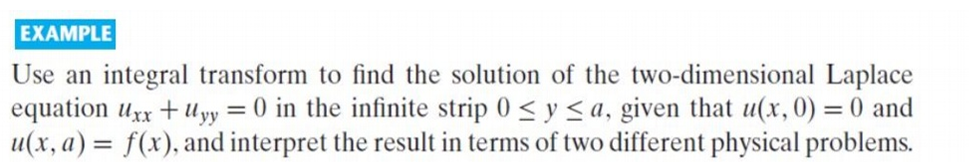

**Using the Fourier transform**

-Choose x as a Fourier variable since going to infinity

-Choose Fourier since no condition

clear
clc
clearvars
syms x y w u(x,y) U(w,y) F(w) C2 Y(y) G(w) a
D2y = diff(u,y,2);
D2x = diff(u,x,2);
y0 = Y(0) == 0

$$y0 = Y\left(0\right)=0$$

ya = Y(a) == F(w)

$$ya = Y\left(a\right)=F\left(w\right)$$

eqn = fourier(D2x+D2y == 0,x,w);
eqn = subs(eqn,{fourier(D2y,x,w),fourier(u,x,w)},{subs(D2y,{u,x},{U,w}),U})

$$eqn(y) = \frac{\partial^{2}}{\partial y^{2}}U\left(w,y\right)-w^{2}\,U\left(w,y\right)=0$$

eqn = subs(eqn,U(w,y),Y(y));
sol = dsolve(eqn);
sol = collect(rewrite(sol,"sinhcosh"),["cosh","sinh"]);
C2 = solve(subs(sol,y,0) == 0,C2);
sol = subs(sol,sym('C2'),C2)

$$sol = 2\,C_{1}\,\sinh\left(w\,y\right)$$

sol_a = subs(sol,{sym('C2'),y},{C2,a});
C1 = solve(sol_a == F(w),sym('C1'))

$$C1 = \frac{F\left(w\right)}{2\,\sinh\left(a\,w\right)}$$

U(w,y) = subs(sol,sym('C1'),C1)

$$U(w, y) = \frac{F\left(w\right)\,\sinh\left(w\,y\right)}{\sinh\left(a\,w\right)}$$

u(x,y) = str2sym('1/sqrt(2*pi)')*int(U*exp(1i*w*x),w,[-inf inf])

$$u(x, y) = \frac{\sqrt{2}\,\int_{-\infty }^{\infty }\frac{{\mathrm{e}}^{w\,x\,\mathrm{i}}\,F\left(w\right)\,\sinh\left(w\,y\right)}{\sinh\left(a\,w\right)}\mathrm{d}w}{2\,\sqrt{\pi }}$$

G(w) = U;G(w) = G/F

$$G(w) = \frac{\sinh\left(w\,y\right)}{\sinh\left(a\,w\right)}$$

u(x,y) = subs(u,str2sym('sinh(w*y)/sinh(a*w)'),str2sym('G(w)'))

$$u(x, y) = \frac{\sqrt{2}\,\int_{-\infty }^{\infty }{\mathrm{e}}^{w\,x\,\mathrm{i}}\,F\left(w\right)\,G\left(w\right)\mathrm{d}w}{2\,\sqrt{\pi }}$$

u = rewrite(u,'sincos')

$$u(x, y) = \frac{\sqrt{2}\,\int_{-\infty }^{\infty }F\left(w\right)\,G\left(w\right)\,\left(\cos\left(w\,x\right)+\sin\left(w\,x\right)\,\mathrm{i}\right)\mathrm{d}w}{2\,\sqrt{\pi }}$$

u = subs(u,sin(w*x),0)

$$u(x, y) = \frac{\sqrt{2}\,\int_{-\infty }^{\infty }\cos\left(w\,x\right)\,F\left(w\right)\,G\left(w\right)\mathrm{d}w}{2\,\sqrt{\pi }}$$